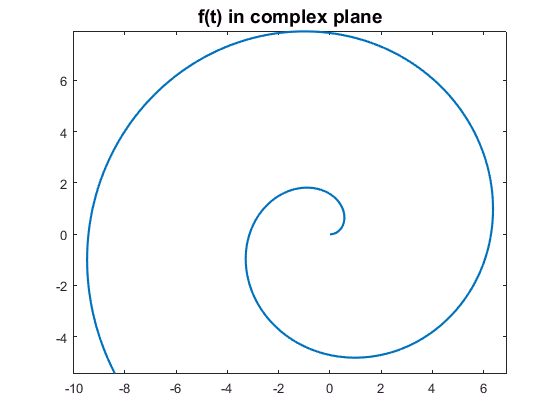

LW = 'linewidth'; lw = 1.6; FS = 'fontsize'; fs = 14;
t = chebfun('t',[0 10],'splitting','on');
f = t.*exp(1i*t);
plot(f,LW,lw), axis equal
title('f(t) in complex plane',FS,fs)

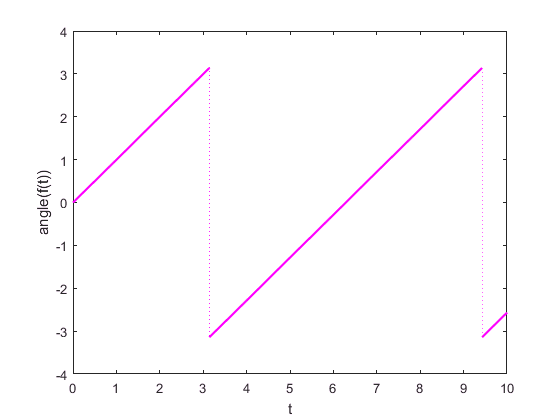

plot(angle(f),'m',LW,lw)
xlabel t, ylabel angle(f(t))

unwrap(angle([-1 -1-.01i]))

ans =     3.1416    3.1516


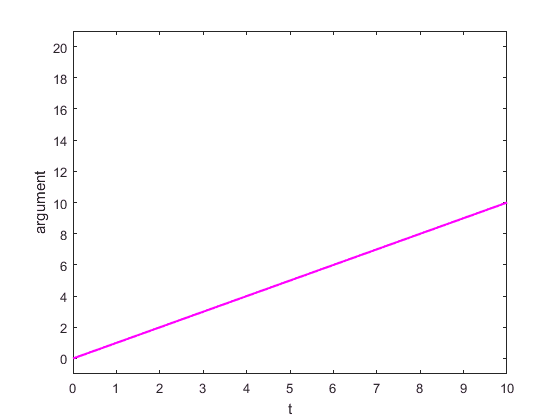

plot(unwrap(angle(f)),'m',LW,lw), ylim([-1 21])
xlabel t, ylabel argument

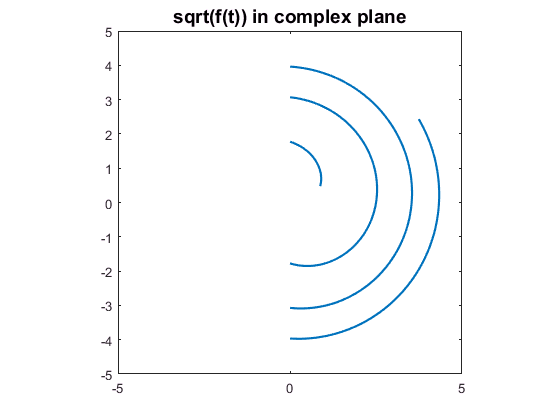

g = chebfun('sqrt(t.*exp(1i*t))',[1 20],'splitting','on');
plot(g,LW,lw), axis(5*[-1 1 -1 1]), axis square
title('sqrt(f(t)) in complex plane',FS,fs)

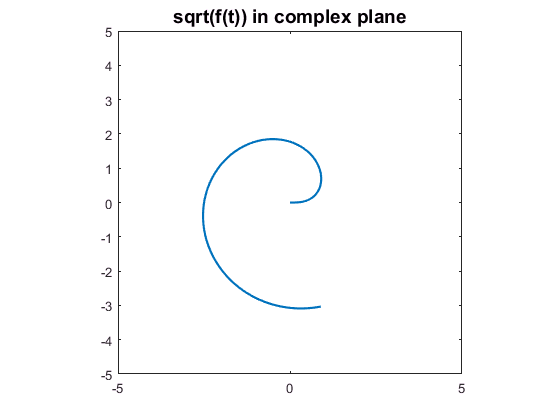

g = sqrt(abs(f)).*exp(.5i*unwrap(angle(f)));
plot(g,LW,lw), axis(5*[-1 1 -1 1]), axis square
title('sqrt(f(t)) in complex plane',FS,fs)

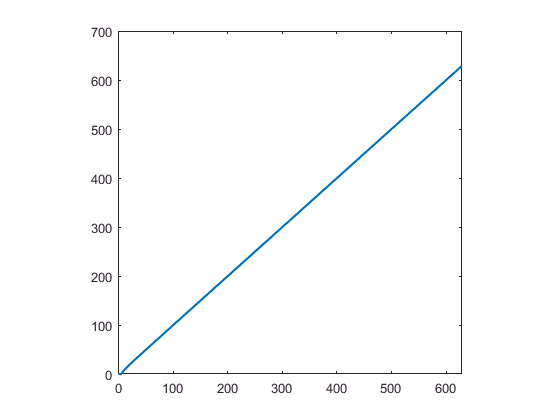

% %
lambda = 1;%633e-9; % Red light wavelength
eps2 =  -18.295 - 1i*0.48085; % Johnson & Christy,1972 (refractiveindex.info) at 633 nm
load em_constants.mat % Contains varepsilon, mu and c
eps_0 = epsilon_0;
eps1 = 1 ;
c = 1/sqrt(mu_0*eps_0);
omega = 2*pi*c/lambda; % angular frequency
eta_0 = sqrt(mu_0/eps_0);
k1 = omega*sqrt(mu_0*eps_0); % propagation constant of air
k2 = omega * sqrt(mu_0*eps_0*eps_silver);
y_int = imag(k2^2)/(2*k1);
kx = chebfun('kx',[0 k1*100],'splitting','on');
kz1 = sqrt(k1^2 - kx.^2);
kz2 = sqrt(k2^2 - kx.^2);
plot(imag(kz1),LW,lw), axis square

D = kz1./eps1 + kz2./eps2;

Undefined function or variable 'eps1'.


G = 1./D;
I = G .* exp(-1i*kx*x);